Loads a pre-trained classifier (`concreteIntensityFeatures.mat) that you made in preparingYourImagesForClassification.mlx file`

load concreteIntensityFeatures.mat

extract feature of test data with the extractConcreteFeatures.m function which you made in previuse file.

testTable = extractConcreteFeatures(dsTest);

`Process new images`

fileLocation = uigetdir();
newImageDS = imageDatastore(fileLocation, "LabelSource","foldernames");
newImageTable = extractConcreteFeatures(newImageDS);

`Classify images with the model you just made with classification learner app.`

[predictedLabels, scores] = trainedModel.predictFcn(newImageTable);

`Visualize results`

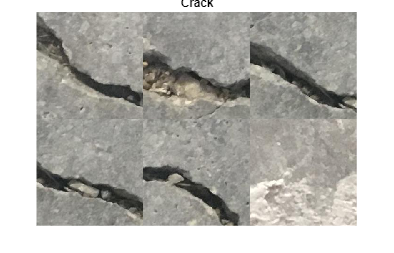

ans = 4

figure;
montage(newImageDS.Files(predictedLabels == "Crack"));
title('Crack');4

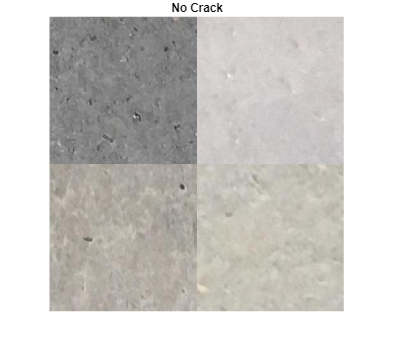

figure;
montage(newImageDS.Files(predictedLabels == "No Crack"));
title('No Crack');